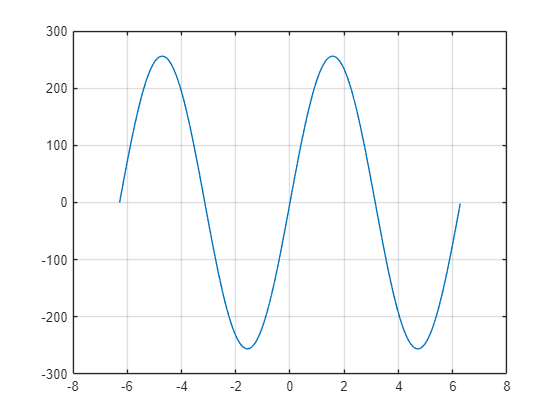

t = -2*pi:0.01:2*pi;
A=256;
y_continua = A*sin(t);
% Graficamos la señal continua
figure;
plot(t, y_continua);
grid on;

frecuencia = 1; 
cantidad_muestras = 11

cantidad_muestras = 11

tiempo_discreto = 0:1:2*cantidad_muestras-1;
figure;
senal_seno_discreta = A*sin(2*pi*frecuencia*tiempo_discreto/cantidad_muestras)

senal_seno_discreta =          0  138.4040  232.8658  253.3943  193.4719   72.1235  -72.1235 -193.4719 -253.3943 -232.8658 -138.4040   -0.0000  138.4040  232.8658  253.3943  193.4719   72.1235  -72.1235 -193.4719 -253.3943 -232.8658 -138.4040


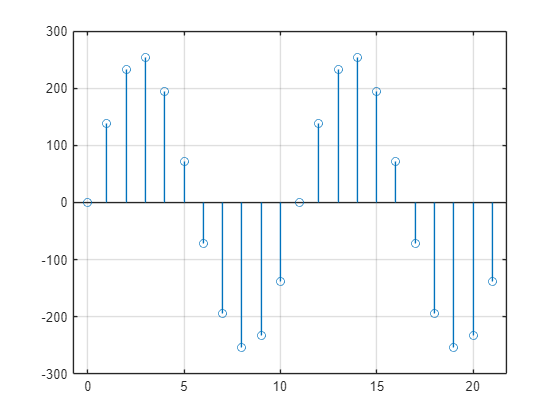

stem(tiempo_discreto, senal_seno_discreta);
grid on;

figure;
senal_seno_discreta_Q = int8(A * sin(2*pi*frecuencia*tiempo_discreto/cantidad_muestras))

senal_seno_discreta_Q = 1×22 int8 row vector
      0    127    127    127    127     72    -72   -128   -128   -128   -128      0    127    127    127    127     72    -72   -128   -128   -128   -128


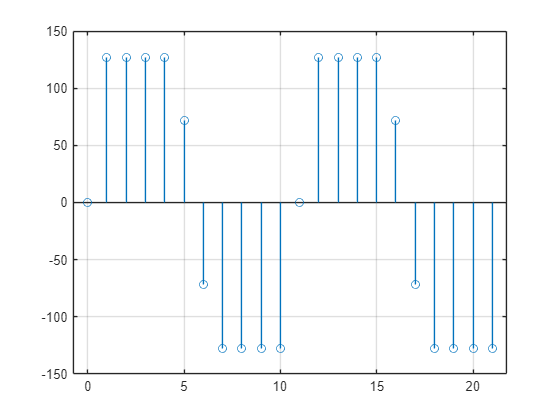

stem(tiempo_discreto, senal_seno_discreta_Q);
grid on;

figure

frecuencia = 1; % Frecuencia de la señal seno discreta (en ciclos por muestra)
cantidad_muestras = 20; % Cantidad de muestras para la señal discreta
tiempo_discreto = 0:1:cantidad_muestras-1; % Dominio del tiempo discreto (muestras)

senal_seno_discreta = round(A * sin(2*pi*frecuencia*tiempo_discreto/cantidad_muestras),1)

senal_seno_discreta =          0   79.1000  150.5000  207.1000  243.5000  256.0000  243.5000  207.1000  150.5000   79.1000         0  -79.1000 -150.5000 -207.1000 -243.5000 -256.0000 -243.5000 -207.1000 -150.5000  -79.1000


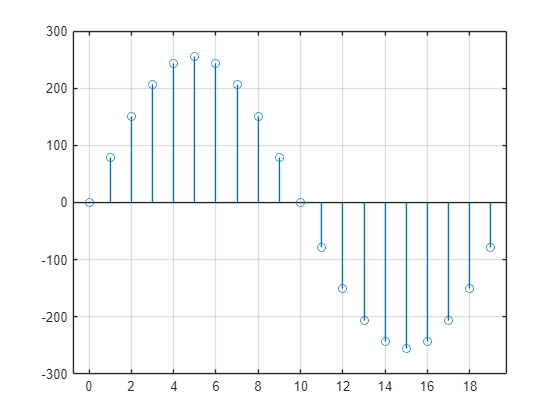


% Graficar la señal seno discreta
stem(tiempo_discreto, senal_seno_discreta);
%xlabel('Tiempo discreto (muestras)');
%ylabel('Amplitud');
%title('Señal Seno Discreta');
grid on;